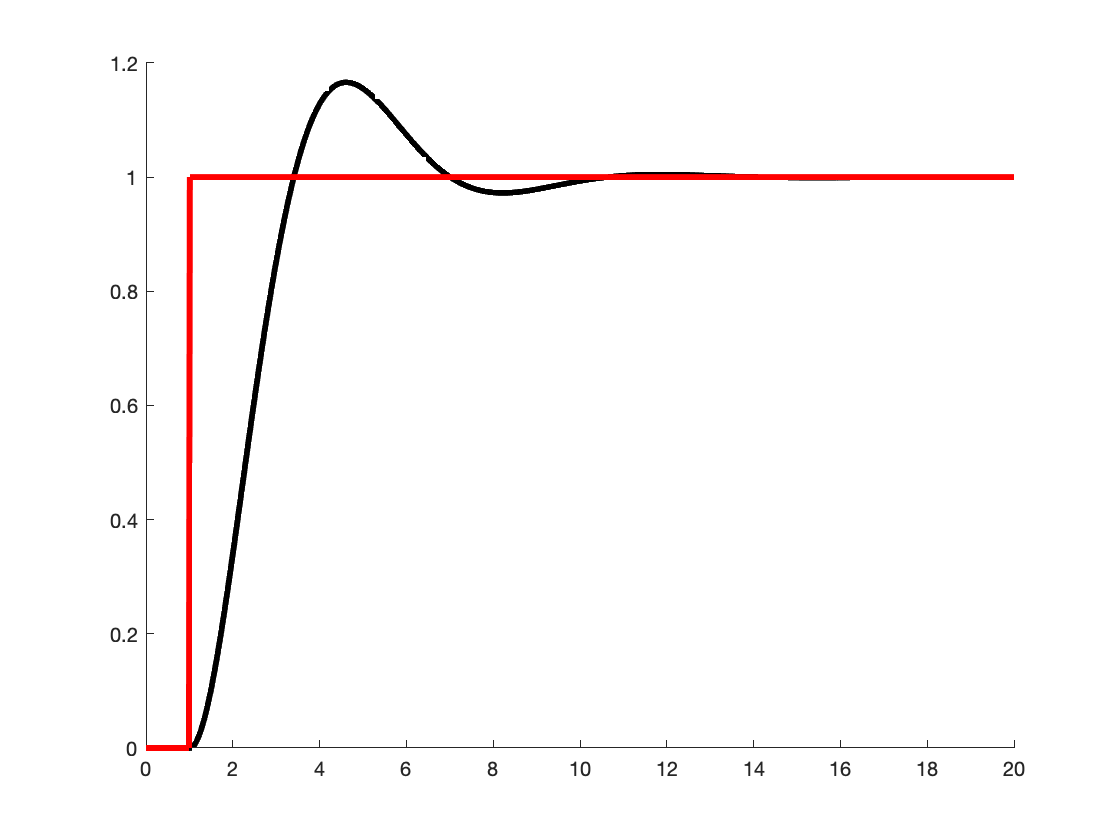

t = 0:0.01:20;


x0 = [0;0];
X = [x0, zeros(2,length(t)-1)];
F = zeros(1,length(t));
dt = t(2) - t(1);

Xd = heaviside(t - 1);
Xdd = [0, diff(Xd)/dt];

Error = x0(1);

for i = 2:length(t) 
    X(2,i) = X(2,i - 1) + F(i)*dt;
    X(1,i) = X(1,i - 1) + X(2,i-1)*dt;
    Error = Error + dt*(Xd(i) - X(1,i));
    if Error > 10
        Error = 10;
    elseif Error < -10
        Error = -10;
    end
    F(i+1) = (Xd(i) - X(1,i)) + (Xdd(i) - X(2,i)) + 0*Error;
    
    if F(i+1) > 1
        F(i+1) = 1;
    elseif F(i+1) < -1
        F(i+1) = -1;
    end
    
end

hold on
plot(t, X(1,:), "Color",'Black', "LineWidth", 3)
plot(t, Xd, "Color",'Red', "LineWidth", 3)
hold off

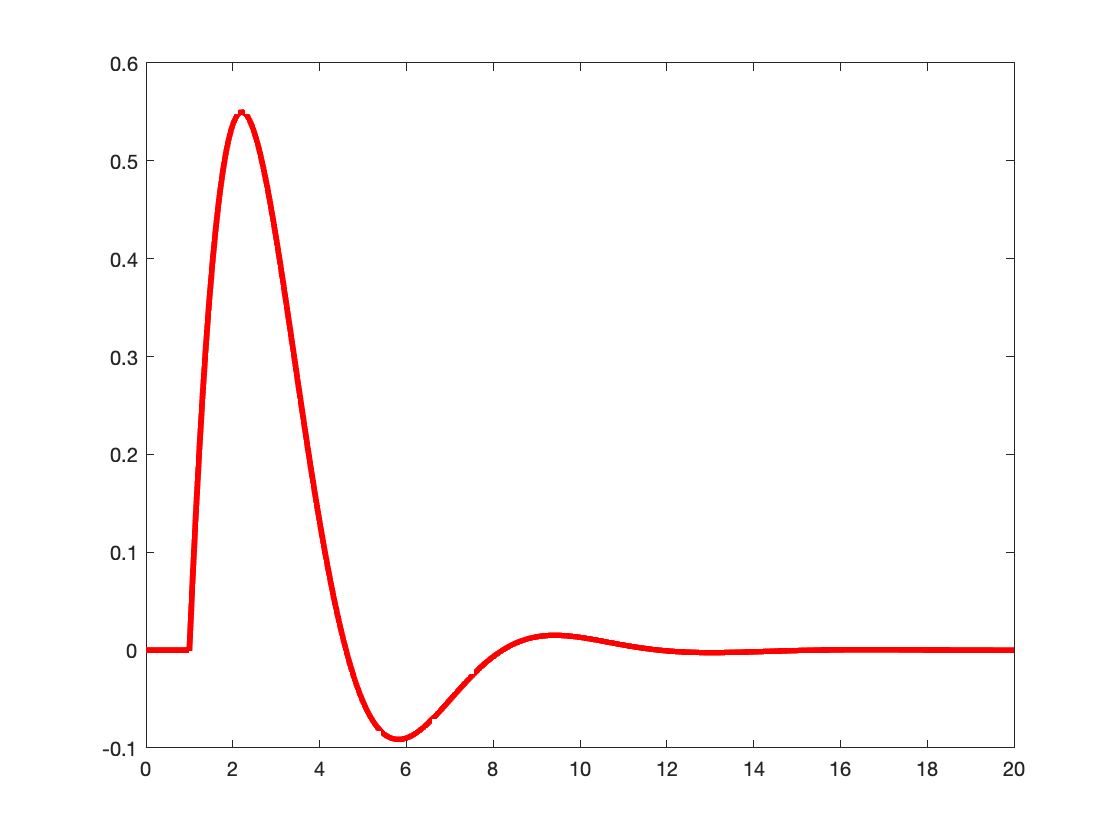

plot(t, X(2,:), "Color",'Red', "LineWidth", 3)

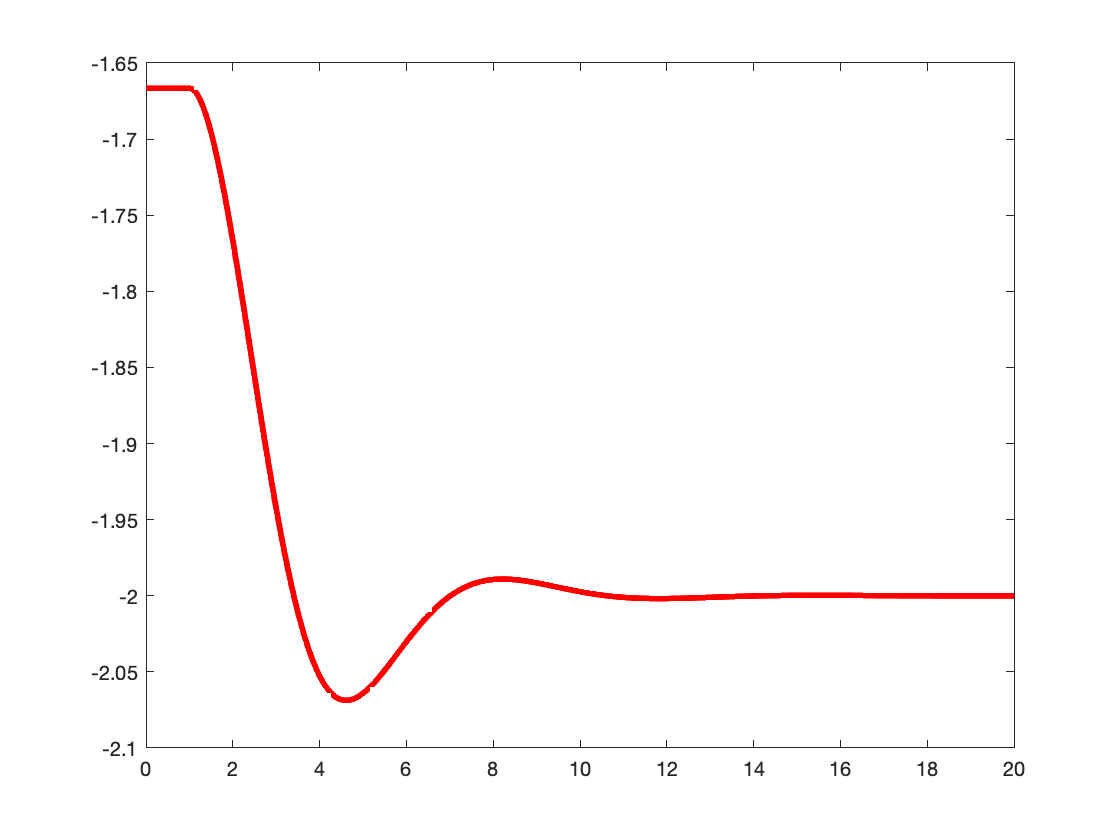

plot(t, barrierFunc(X(1,:)), "Color",'Red', "LineWidth", 3)

function out = barrierFunc(in)
    out = -10./abs(in - 6);
end